# Identification and Estimation Exam (solution)

# December 12 2023

**Open book, open internet, no communication with human beeing allowed**

This exam is a "matlab live script" : a format that mix text and executable code. Each "section" can be run separately (Tab LIVE EDITOR/Run Section). The outputs is shown on right.

You will be asked:

- to complete, modify and comment matlab code. (into "code" sections)

- to answer literal questions (into "text" sections)

Two parts. Finding a correct model (part I) and a correct state estimate (part II.) will secure 10/20. Good comments and discussion will give additional points.

# Part I. Identification

The goal is to identify and validate the discrete linear model of a system sampled at $\textrm{Ts}=0\ldotp 1s$. 

## 1.1 Load data (this section not supposed to be modified)

A system is excited in three ways:

- a PRBS signal (duration 100s)

- two 211 manoeuvers (duration 100s)

- a simple step input (duration 15s)

load('exam23data.mat');
Tprbs = Ts*(1:length(uprbs))

Tprbs =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


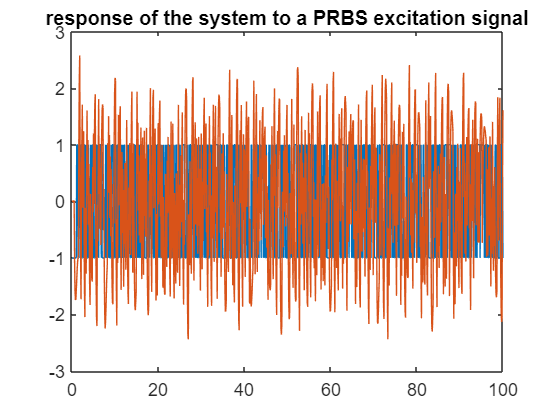

plot(Tprbs,uprbs,Tprbs,yprbs);title('response of the system to a PRBS excitation signal');

T211 = Ts*(1:length(u211))

T211 =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


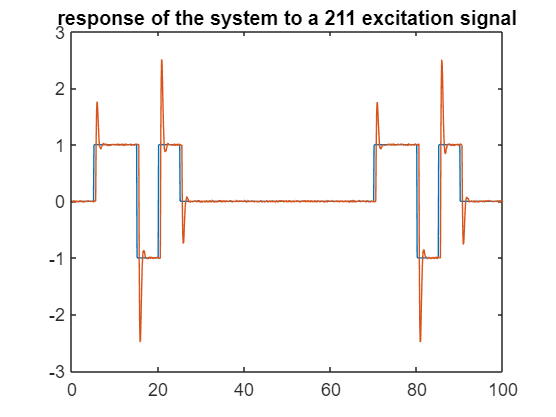

plot(T211,u211,T211,y211);title('response of the system to a 211 excitation signal');

Tstep = Ts*(1:length(ustep))

Tstep =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


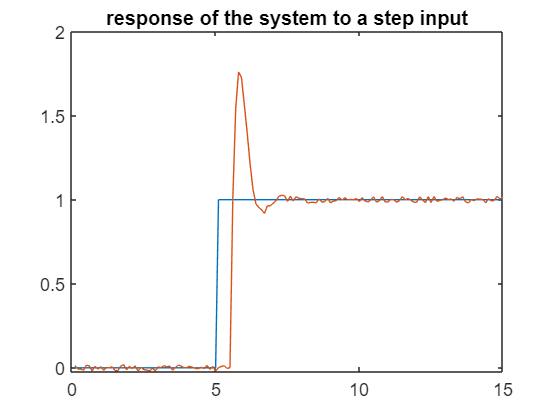

plot(Tstep,ustep,Tstep,ystep);title('response of the system to a step input');

## 1.2 Identification and validation (section to be modified)

You are asked to:

- find the best linear model of the system, based on the RLS and ELS algorithm given below (not supposed to be modified)

- discuss the identification procedure (choice of na,nb,nc,nk,D0,B0,C0)

- discuss the validation procedure and criteria

In the next two sections (I.2.1 and I.2.2) we give the very basic steps of an identification and validation procedure. You will **modify the code** and insert comments in **Text sections**.

### I.2.1 Identification

uident = uprbs;
yident = yprbs;

%Evaluating delay
na = 0;
nb = 100;
nk =0;
nc = 0;
D0 = 1*eye(na+nb+nc);
A0 = zeros(na,1);
B0 = zeros(nb,1);
C0 = zeros(nc,1);
% [A,B,C] = ELS(uident,yident,na,nb,nc,nk,D0,A0,B0,C0)
[A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0)

A = 1

B =          0   -0.0003   -0.0005   -0.0001   -0.0003    1.0020    0.5499    0.1990   -0.0286   -0.1494   -0.1871   -0.1738   -0.1343   -0.0884   -0.0468   -0.0150    0.0049    0.0157    0.0183    0.0162    0.0125    0.0086    0.0041    0.0013   -0.0003   -0.0017   -0.0016   -0.0013   -0.0013   -0.0011   -0.0005    0.0001   -0.0001   -0.0003    0.0000    0.0004    0.0001   -0.0001   -0.0004    0.0004    0.0002   -0.0001   -0.0005    0.0002   -0.0001    0.0002    0.0006    0.0010   -0.0000    0.0003


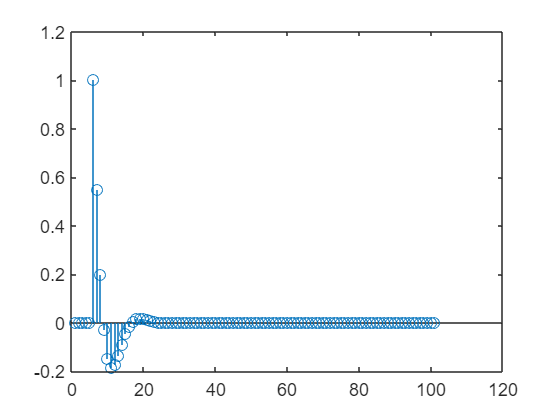

stem(B)

%using algorithms
na = 5;
nb = 5;
nk = 4;
nc = 0;% nc = 1 if els is used, else taken as 0 for rls
D0 = 1*eye(na+nb+nc);
A0 = zeros(na,1);
B0 = zeros(nb,1);
C0 = zeros(nc,1);

% [A,B,C] = ELS(uident,yident,na,nb,nc,nk,D0,A0,B0,C0)
[A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0)

A =     1.0000   -0.3857   -0.1344   -0.0623   -0.0337    0.1565


B =          0         0         0         0         0    1.0022    0.1633   -0.1475   -0.2419   -0.2328


For evaluating delay -> nk = 4 for prbs

nk = 3 for 211

### I.2.2 Validation

%Choice of data for validation
uvalid = uprbs;
yvalid = yprbs;

%Generation of a LTI system from the identified model
num = B;
den = A;
sysid = tf(num,den,Ts,'variable','z^-1')

sysid =
 
     1.002 z^-5 + 0.1633 z^-6 - 0.1475 z^-7 - 0.2419 z^-8 - 0.2328 z^-9
  -------------------------------------------------------------------------
  1 - 0.3857 z^-1 - 0.1344 z^-2 - 0.06228 z^-3 - 0.03372 z^-4 + 0.1565 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.



yid = lsim(sysid,ustep,Tstep);

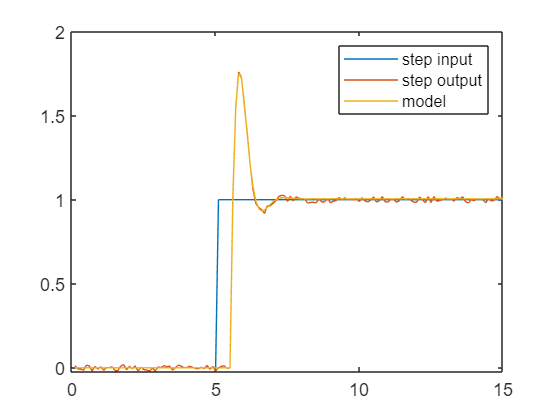


%Compare step response of real system and identified system
plot(Tstep,ustep,Tstep,ystep,Tstep,yid);legend('step input','step output','model');


%Compute prediction error, sum of square of errors, Akaike criteria
% [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C)
[err, J, AIC] = computerrors(uvalid,yvalid,A,B)

err =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0115


J = 1.6035e-04

AIC = -8.7101

N = length(uvalid);
x = xcorr(err,err);
mean(err) %to study nature of noise

ans = -2.1483e-04

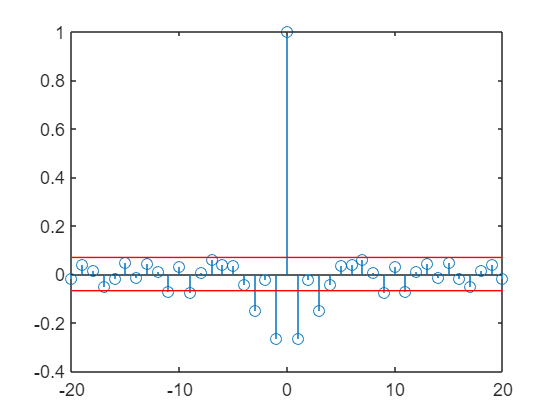

x = x/x(N);
stem(-20:1:20,x(N-20:N+20));
line([-20 20],[2.17/sqrt(N) 2.17/sqrt(N)],'color','r');
line([-20 20],[-2.17/sqrt(N) -2.17/sqrt(N)],'color','r');

## I.3 Various questions

- What is the interest of Extended Least Square (here els) compared to the Ordinary Least square (here rls)?

- What is the interest of the PRBS signal excitation compared to a step input or a 211 manoeuver?

- In this case, the mean(err) is found to be of the order of magnitude of 10^-4, which can be approximated to be 0. Thus, the noise can be assumed to be additive gaussian white noise. Hence, the RLS is sufficient to obtain the solution for the model. ELS is more time consuming, and is unnecessary in this case. 

- The prbs and 211 input signals are found to be ideal to be used for the identification process. This is primarily because prbs and 211 has low additive noise (from the mean(error), hence, better to use rls with this, and rls process is less time consuming than els, and prbs has the least error of the two. For the case of step input, els is required since with rls, it was not possible to achieve go fit, indicating the presence of a non-white noise, confirmed by the much higher value of the mean(error).

            However, for the validation, the step response can be used as a much better way of comparing how good the fit it in the reponse curve. 

if prbs is used, the delay nk is found to be 5;

if 211 is used, the delay nk is found to be 4

the na and nb paramters were found to be na = 5 and nb=5 for both these inputs. 

however, if step is used, the delay nk is extremely high value. 

Thus, prbs is a much better choice for the estimation, used with rls. 

# **Part 2. Extended Kalman filtering **

## **2.1 Generate data (section not to be modified)**

A discrete process is driven by the linear discrete equation:


$$\begin{array}{l}
x\left(t+1\right)=0\ldotp 99\;{\cos \left(x\left(t\right)\right)} +e\left(t\right)+v\left(t\right)\\
y\left(t\right)=2+{x\left(t\right)}^3 +w\left(t\right)
\end{array}$$


where :

- $x\left(t\right)$ is the internal state

- $e\left(t\right)$ is a control input

- $v\left(t\right)$ is a zero mean random noise

- $w\left(t\right)$ is a zero mean random noise

In the following code we simulate the output when the input is a pseudo random binary signal. The "real" state x(t) is simulated and will be estimated in the next questions. (This section must be executed before the next ones).

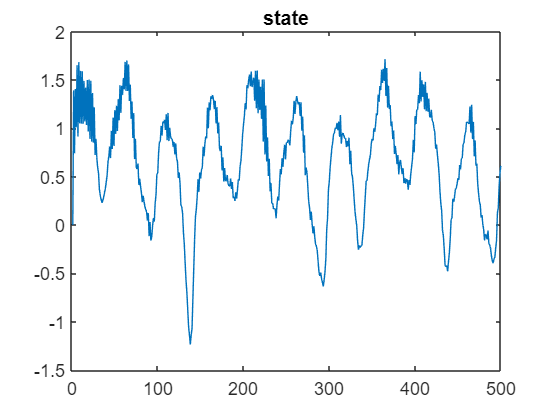

N=500; %number of time steps
x = zeros(1,N);
y =zeros(1,N);
e = 0.2*sin(2*pi/20*[1:N]) + 1*sin(2*pi/50*[1:N]) + 0.5*sin(2*pi/170*[1:N]);% 
v = 0.05*randn(1,N); % Gaussian distributed noise
w = 0.2*rand(1,N); % Uniform distriobuted noise
for t=2:N
    %simulate output and internal state
    x(t) = 0.99*(cos(x(t-1))) + e(t) + v(t);
    y(t) = 2 + x(t)^3 + w(t);
end
plot(1:N,x);title('state');

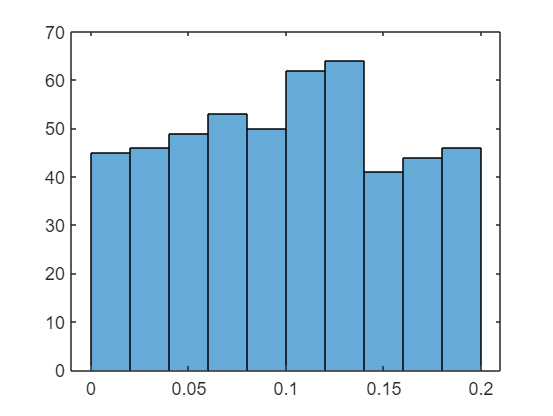

histogram(w);

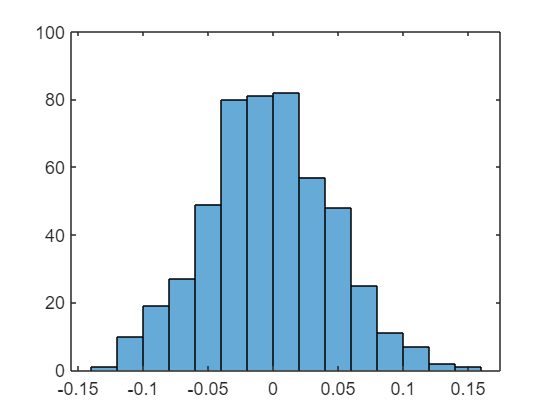

histogram(v);

## 2.2 Kalman filter (section to be modified)

We want to compute the estimate xe(t) of the state x(t) using only the known input e(t) and measured output y(t).

You are asked to:

- code and tune (P,Q,R) your Kalman filter

- discuss the validation procedure and criteria

You will **modify the code** and insert comments in **Text sections**.

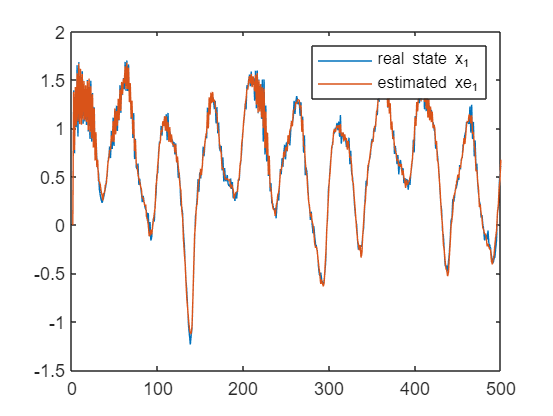

P = 0.01;  %initial value of the filter covariance error (Kalman filter)
Q = 0.001;  %variance of the additive filter state noise
R = 0.02;  %variance of the additive filter measurement noise
xe = 0; %initial value of the filter estimated state
ypred = 0;
for t = 2:N
    %estimate the state x(t)
    %your code begins here
    %predict
    xe(t) = 0.99*cos(xe(t-1)) + e(t) + sqrt(Q)*randn(1,1); % To be modified
    A = 0.7; % To be modified
    P = A*P*A'+Q;
    %Update
    ypred(t) = 2+ (xe(t)).^3 + sqrt(R)*randn(1,1); % To be modified
    C = 0.8; % To be modified
    K = P*C'*inv(C*P*C'+R);
    P = P-K*C*P;
    xe(t) = xe(t)+K*(y(t)-ypred(t));
    %end of your code
end
close all;
plot(1:N,x,1:N,xe)
% plot(1:N,x,1:N,xe, 1:N,xe-3*sqrt(P),'b',1:N,xe+3*sqrt(P),'b');
legend('real state x_1','estimated xe_1');


%mean square error - effectiveness of the estimation algorithm
x_k=xe;
err_k =x-x_k;
mse_k = (err_k*err_k')/N

mse_k = 0.0031

## 2.3 I.3 Various questions

- Is our the Kalman filter of our example optimal?

Kalman filter works under the assumption that the noise is additive and gaussian normal noise. However, since the sensor noise is uniform and not normal, the kalman filter is not the best choice for the state estimation. Thus, the result obtained could the best using kalman. It is to be investigated if the mean square error from particle filter could be lesser than the already very low mean square error from kalman filter. 

The tuning of the Kalman Filter parameters - P,Q,R and A and C were verified using the mean squre error. 

- Discuss the interest of the Particle filter compared to the Kalman filter for this precise example?

The particle filter could be a better choice, since it does not require to work under the assumption that all noise is gaussian/normal. 

# Identification and validation functions, not supposed to be modified

### Recursive Least Square

function [A,B] = RLS(uid,yid,na,nb,nk,D0,A0,B0)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
% theta = zeros(na+nb,1);
theta = [A0;B0];
% D = 10^6*eye(na+nb);
D = D0;
%Recursive algorithm
for t = max([na nb+nk]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1)];
    yhatprior = theta'*phi;
    eps0 = yid(t+1)-yhatprior;
    epsposterior = eps0/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior;
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end
A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
end

### Recursive Extended Least Square

function [A,B,C] = ELS(uid,yid,na,nb,nc,nk,D0,A0,B0,C0)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
% theta = zeros(na+nb+nc,1);
theta = [A0;B0;C0];
% D = 10^6*eye(na+nb+nc);
D = D0;
epsposterior = zeros(length(yid),1);
eps0 = zeros(length(yid),1);
%Recursive algorithm
for t = max([na nb+nk nc]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1);epsposterior(t:-1:t-nc+1)];
    yhatprior = theta'*phi;
    eps0(t+1) = yid(t+1)-yhatprior;
    epsposterior(t+1) = eps0(t+1)/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior(t+1);
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end

A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
C = theta(na+nb+1:end)';
end

### Prediction Error and AIC criteria

AIC criteria combines the quality of the fit (J) with the complexity of the model.

function [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C)
N = length(uvalid);
if nargin == 4
    C = [];
end
uvalid = reshape(uvalid,[],1);
yvalid = reshape(yvalid,[],1);
A = A(2:end);
B = B(2:end);
na=length(A);
nb=length(B);
nc=length(C);
theta = [A';B';C'];
err = zeros(N,1);
%Recursive algorithm
for t = max([na nb nc]):(length(yvalid)-1)
    phi = [-yvalid(t:-1:t-na+1);uvalid(t:-1:t-nb+1);err(t:-1:t-nc+1)];
    err(t+1) = yvalid(t+1)-theta'*phi;
end
J = 1/N*(err'*err);
AIC = log(J)+2*(na+nb+nc)/N;
end